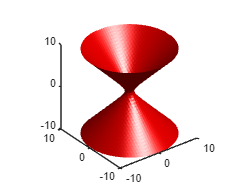

clear all;
[X,Y,Z] = meshgrid(-10:0.5:10,-10:0.5:10,-10:0.5:10);
a=1;
b=1;
c=1;
V = X.^2/a^2 + Y.^2/b^2 - Z.^2/c^2;
p=patch(isosurface(X,Y,Z,V,1)); % This is the key step. It involves getting the part of the volume corresponding to the surface defined by the equation
set(p,'FaceColor','red','EdgeColor','none');
daspect([1 1 1])
view(3);
camlight

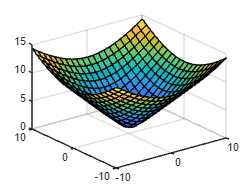

[x,y]=meshgrid(-10:10);
r_sq=x.^2+y.^2;
z=sqrt(r_sq+1);
surf(x,y,z)

Ceci est un exemple dpour verifier si on obtient bien une hyperbole

clc;
clear all;
Sell = [12,22,28];
Price1 = [15,30,50];
Buy = [10,18,29];
Price2 = [25,42,50];
plot(Sell, Price1, 'b.-', 'LineWidth', 2, 'MarkerSize', 20);
grid on;
hold on;
plot(Buy, Price2, 'r.-', 'LineWidth', 2, 'MarkerSize', 20);
legend('Sell', 'Buy', 'location', 'southeast');

% extract the polynomial coefficient 
coeff1 = polyfit(Sell(2:3),Price2(2:3),1)

coeff1 =           1.33333333333333          12.6666666666667


coeff2 = polyfit(Buy(2:3), Price2(2:3),1)

coeff2 =          0.727272727272727          28.9090909090909



% expression de la pente, de la forme k = (y2 - y1) / (x2 - x2)
matchPrice = (coeff2(2) - coeff1(2)) / (coeff1(1) - coeff2(1))

matchPrice =                       26.8


% de la forme : x * k + y ou a * x + b , fonction affine
y = coeff1(1) * matchPrice + coeff1(2)

y =                       48.4


% Find the overall range
minPrice = min(min([Sell; Price1; Buy; Price2]))

minPrice =     10

maxPrice = max(max([Sell; Price1; Buy; Price2]))

maxPrice =     50


% Interpolate extra points to get more accuracy for non-linear curves.
% We'll get to the nearest 1/1000 of a cent.
numPoints = round((maxPrice - minPrice) * 1000)

numPoints =        40000


% Get all possible "x" values
x = linspace(minPrice, maxPrice, numPoints)

x =                         10          10.0010000250006          10.0020000500013          10.0030000750019          10.0040001000025          10.0050001250031          10.0060001500038          10.0070001750044           10.008000200005          10.0090002250056          10.0100002500063          10.0110002750069          10.0120003000075          10.0130003250081          10.0140003500088          10.0150003750094            10.01600040001          10.0170004250106          10.0180004500113          10.0190004750119          10.0200005000125          10.0210005250131          10.0220005500138          10.0230005750144           10.024000600015          10.0250006250156          10.0260006500163          10.0270006750169          10.0280007000175          10.0290007250181          10.0300007500188          10.0310007750194            10.03200080002          10.0330008250206          10.0340008500213          10.0350008750219          10.0360009000225          10.0370009250231        


% Interpolate the other arrays at the new x points.
Price1a = interp1(Sell, Price1, x)

Price1a =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


Price2a = interp1(Buy , Price2, x)

Price2a =                         25          25.0021250531263          25.0042501062527           25.006375159379          25.0085002125053          25.0106252656316           25.012750318758          25.0148753718843          25.0170004250106           25.019125478137          25.0212505312633          25.0233755843896          25.0255006375159          25.0276256906423          25.0297507437686          25.0318757968949          25.0340008500213          25.0361259031476          25.0382509562739          25.0403760094002          25.0425010625266          25.0446261156529          25.0467511687792          25.0488762219055          25.0510012750319          25.0531263281582          25.0552513812845          25.0573764344109          25.0595014875372          25.0616265406635          25.0637515937898          25.0658766469162          25.0680017000425          25.0701267531688          25.0722518062952          25.0743768594215          25.0765019125478          25.0786269656741  


% Find differences at every x value.
priceDifference = abs(Price2a - Price1a)

priceDifference =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN



% Find there the difference is minimum
[minDiff, indexOfMinDiff] = min(priceDifference)

minDiff =        0.00126972871291287

indexOfMinDiff =        17721


% Get the x value there.
xMatch = x(indexOfMinDiff)

xMatch =           27.7204430110753


% Find out where the lines are equal.
% il cherche la pente ? ou une matrice
% ax + b = cx + d.  Find x
% x = (d-b) / (a-c)
matchPrice1 = Price1a(indexOfMinDiff)

matchPrice1 =           49.0681433702509

matchPrice2 = Price2a(indexOfMinDiff)

matchPrice2 =           49.0694130989638

yMatch = mean([matchPrice1, matchPrice2])

yMatch =           49.0687782346074

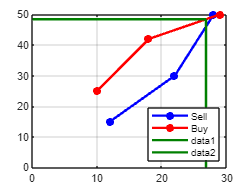





% Draw lines in dark green color.
darkGreen = [0, 0.5, 0];
line([matchPrice, matchPrice], [0, y], 'Color', darkGreen, 'LineWidth', 2);
line([0, matchPrice], [y, y], 'Color', darkGreen, 'LineWidth', 2);